clear
load COVID_hospitalization_T-New_predictors.mat%flu_hospitalization_T.mat
% load flu_hospitalization_TOP-New_predictorsFluSurv2 %flu_hospitalization_TOP-New_predictorsFluSurv
popu = load('us_states_population_data.txt');
% old_data = table;
% for i=2019:-1:2016
%     load("flu_hospitalization_TOP-New_predictors" + int2str(i)+".mat")
%     old_data = [predILI; old_data];
% end
% old_data_no2020 = [PedILI_Old; old_data];
% old_data_no2020 = PedILI_Old;
days = size(H,1)/56; 

%% Add population data
% st = table;
% for i = 1:56
%     st = [st; array2table(repmat(i,239,1))];
% end
% st = repmat(st,11,1);
% % H(:,end+1) = H(:,2);
% old_data_no2020(:,end+1) = st;
st = table;
for i = 1:56
    st = [st; array2table(repmat(i,days,1))];
end
H(:,end+1) = st;
for i = 1:length(popu)
%     old_data_no2020.Var127(old_data_no2020.Var127 == i) = popu(i);
%     old_data_no2020.Var127(isnan(old_data_no2020.Var2)) = nan;
    H.Var223(H.Var223 == i) = popu(i);
end
%% Normalize data
H2 = H;
% old_data_no20202 = old_data_no2020;
for i =1:126
    H2(:,i) = array2table(eval(['H2.Var' num2str(i)]) * 100000./H2.Var223);
%     old_data_no20202(:,i) = array2table(eval(['old_data_no20202.Var' num2str(i)]) * 100000./old_data_no20202.Var127);
end
%% Rename predictors
rlags_options = ["r0" "r7"];
un_list = ["un1" "un2" "un3"];
halpha_list = [];
for alph =  [0.93 0.96 0.99]
    alpha = "alpha" + alph;
    halpha_list = [halpha_list alpha];
end
w = ["4m" "6m" "8m"];
[X1, X2, X3, X4] = ndgrid(un_list, rlags_options, halpha_list, w);
scen_list = [X1(:), X2(:), X3(:), X4(:)];

H2 = renamevars(H2,["Var1", "Var2", "Var223"],["wkbhnd", "incwk","pop"]);
% old_data_no20202 = renamevars(old_data_no20202,["Var1", "Var2", "Var127"],["wkbhnd", "incwk","pop"]);
for wk=1:4
    for i=1:size(scen_list,1)
        nb = (wk-1)*size(scen_list,1)+ (6+i);
        old_var = "Var"+nb;
        var_name_new = wk+join(scen_list(i,:),"");
        H2 = renamevars(H2,old_var,var_name_new);
%         old_data_no20202 = renamevars(old_data_no20202,old_var,var_name_new);
    end
end
%%
% data_train = table;
% wks_back = 0;
% for i=1:(size(H2,1)/(days*11)) %Basically looping over states
%     data_train = [data_train; H2(days*(i-1) + 1 :(days*i)-(7*wks_back),:)];
% end
% figure(2)
% plot(data_train{1:days,2});
%% Data split for newer data
for wks_back = 1:1
    data_train = table;
    data_test = table;
    for i=1:(size(H2,1)/days) %Basically looping over states
        data_train = [data_train; H2(days*(i-1) + 1:(days*i)-(7*wks_back),:)];
        data_test = [data_test; H2((days*i)-(7*wks_back) + 1:days*i -(7*(wks_back-1)),:)];
    end
    %%% Replicate this year's data (Training data)
%     train_temp = data_train;
%     rep = 2; %(increase it by rep+1 times)
%     for i = 1:rep
%         train_temp = [train_temp; data_train];
%     end
%     data_train = train_temp;
    %%%
    tic;
    Mdl_1 = TreeBagger(56,[data_train(:,[1 2 7:60 223])],[data_train.Var3],'Method','regression');
    Mdl_2 = TreeBagger(56,[data_train(:,[1 2 61:114 223])],[data_train.Var4],'Method','regression');
    Mdl_3 = TreeBagger(56,[data_train(:,[1 2 115:168 223])],[data_train.Var5],'Method','regression');
    Mdl_4 = TreeBagger(56,[data_train(:,[1 2 169:222 223])],[data_train.Var6],'Method','regression');
%     Mdl_1 = TreeBagger(56,[old_data_no20202(:,[7:36]);data_train(:,[7:36])],[old_data_no20202.Var3; data_train.Var3],'Method','regression');%,'Options',paroptions);
%     Mdl_2 = TreeBagger(56,[old_data_no20202(:,[37:66]);data_train(:,[37:66])],[old_data_no20202.Var4; data_train.Var4],'Method','regression');%,'Options',paroptions);
%     Mdl_3 = TreeBagger(56,[old_data_no20202(:,[67:96]);data_train(:,[67:96])],[old_data_no20202.Var5; data_train.Var5],'Method','regression');%,'Options',paroptions);
%     Mdl_4 = TreeBagger(56,[old_data_no20202(:,[97:126]);data_train(:,[97:126])],[old_data_no20202.Var6; data_train.Var6],'Method','regression');%,'Options',paroptions);
toc;
%     %view(Mdl_1.Trees{1}, 'Mode', 'graph')
    tic;
    predX_1 = data_test(:,[1 2 7:60 223]);%data_test(:,[1 2 13 15 16 18 19 21 22 24 127]);
    mpgMean_1 = predict(Mdl_1,predX_1);
    mpgQuartiles_1 = quantilePredict(Mdl_1,predX_1,'Quantile',[0.010, 0.025, 0.050, 0.100, 0.150, 0.200, 0.250, 0.300, 0.350, 0.400, 0.450, 0.500, 0.550, 0.600, 0.650, 0.700, 0.750, 0.800, 0.850, 0.900, 0.950, 0.975, 0.990]);
    predX_2 = data_test(:,[1 2 61:114 223]);
    mpgMean_2 = predict(Mdl_2,predX_2);
    mpgQuartiles_2 = quantilePredict(Mdl_2,predX_2,'Quantile',[0.010, 0.025, 0.050, 0.100, 0.150, 0.200, 0.250, 0.300, 0.350, 0.400, 0.450, 0.500, 0.550, 0.600, 0.650, 0.700, 0.750, 0.800, 0.850, 0.900, 0.950, 0.975, 0.990]);
    predX_3 = data_test(:,[1 2 115:168 223]);
    mpgMean_3 = predict(Mdl_3,predX_3);
    mpgQuartiles_3 = quantilePredict(Mdl_3,predX_3,'Quantile',[0.010, 0.025, 0.050, 0.100, 0.150, 0.200, 0.250, 0.300, 0.350, 0.400, 0.450, 0.500, 0.550, 0.600, 0.650, 0.700, 0.750, 0.800, 0.850, 0.900, 0.950, 0.975, 0.990]);
    predX_4 = data_test(:,[1 2 169:222 223]);
    mpgMean_4 = predict(Mdl_4,predX_4);
    mpgQuartiles_4 = quantilePredict(Mdl_4,predX_4,'Quantile',[0.010, 0.025, 0.050, 0.100, 0.150, 0.200, 0.250, 0.300, 0.350, 0.400, 0.450, 0.500, 0.550, 0.600, 0.650, 0.700, 0.750, 0.800, 0.850, 0.900, 0.950, 0.975, 0.990]);
    toc;
    %%%
    % cid = 3;
    % clear days;
    % start_Date = datetime('now') - days(7*wks_back);
    % % start_Date = datetime('now');
    % start_Date.Format = 'yyyy-MM-dd';
    % pred_Dates2 = [start_Date:datetime('now')-1];%- days(7*4)];
    % % pred_Dates2 = [start_Date+days(1):start_Date+days(7*4 + 1)];
    % tiledlayout(2, 2, 'TileSpacing','compact');
    % nexttile;plot(pred_Dates2,data_test.Var4((cid-1)*(7*wks_back) + 1:(cid-1)*(7*wks_back) + (7*wks_back))*popu(cid)/100000,'o'); hold on;
    % plot(pred_Dates2,mpgMean_1((cid-1)*(7*wks_back) + 1:(cid-1)*(7*wks_back) + (7*wks_back),:)*popu(cid)/100000);hold on;
    % plot(pred_Dates2,mpgQuartiles_1((cid-1)*(7*wks_back) + 1:(cid-1)*(7*wks_back) + (7*wks_back),[2 12 22])*popu(cid)/100000);
    % ylabel('Model1wk');
    % % xlabel('Days');
    % legend('Mean','2.5% quantile','Median','97.5% quantile'); %'Mean Response',(2nd term)
    % nexttile;plot(pred_Dates2,data_test.Var5((cid-1)*(7*wks_back) + 1:(cid-1)*(7*wks_back) + (7*wks_back))*popu(cid)/100000,'o'); hold on;
    % plot(pred_Dates2,mpgMean_2((cid-1)*(7*wks_back) + 1:(cid-1)*(7*wks_back) + (7*wks_back),:)*popu(cid)/100000);hold on;
    % plot(pred_Dates2,mpgQuartiles_2((cid-1)*(7*wks_back) + 1:(cid-1)*(7*wks_back) + (7*wks_back),[2 12 22])*popu(cid)/100000);
    % ylabel('Model2wk');
    % nexttile; plot(pred_Dates2,data_test.Var6((cid-1)*(7*wks_back) + 1:(cid-1)*(7*wks_back) + (7*wks_back))*popu(cid)/100000,'o'); hold on;
    % plot(pred_Dates2,mpgMean_3((cid-1)*(7*wks_back) + 1:(cid-1)*(7*wks_back) + (7*wks_back),:)*popu(cid)/100000);hold on;
    % plot(pred_Dates2,mpgQuartiles_3((cid-1)*(7*wks_back) + 1:(cid-1)*(7*wks_back) + (7*wks_back),[2 12 22])*popu(cid)/100000);
    % ylabel('Model3wk');
    % nexttile; plot(pred_Dates2,data_test.Var7((cid-1)*(7*wks_back) + 1:(cid-1)*(7*wks_back) + (7*wks_back))*popu(cid)/100000,'o'); hold on;
    % plot(pred_Dates2,mpgMean_4((cid-1)*(7*wks_back) + 1:(cid-1)*(7*wks_back) + (7*wks_back),:)*popu(cid)/100000);hold on;
    % plot(pred_Dates2,mpgQuartiles_4((cid-1)*(7*wks_back) + 1:(cid-1)*(7*wks_back) + (7*wks_back),[2 12 22])*popu(cid)/100000);
    % ylabel('Model4wk');
    %%% Find across all US
    total_US_GT_1 = [];
    total_US_Mean_1 = [];
    total_US_QT_1 = nan(1,23);
    total_US_GT_2 = [];
    total_US_Mean_2 = [];
    total_US_QT_2 = nan(1,23);
    total_US_GT_3 = [];
    total_US_Mean_3 = [];
    total_US_QT_3 = nan(1,23);
    total_US_GT_4 = [];
    total_US_Mean_4 = [];
    total_US_QT_4 = nan(1,23);
    
    for i=1:(7*wks_back)
        total_US_GT_1(i) = nansum(data_test.Var3(i:(7*wks_back):end));
        total_US_Mean_1(i) = nansum(mpgMean_1(i:(7*wks_back):end));
        
        total_US_GT_2(i) = nansum(data_test.Var4(i:(7*wks_back):end));
        total_US_Mean_2(i) = nansum(mpgMean_2(i:(7*wks_back):end));
        
        total_US_GT_3(i) = nansum(data_test.Var5(i:(7*wks_back):end));
        total_US_Mean_3(i) = nansum(mpgMean_3(i:(7*wks_back):end));
        
        total_US_GT_4(i) = nansum(data_test.Var6(i:(7*wks_back):end));
        total_US_Mean_4(i) = nansum(mpgMean_4(i:(7*wks_back):end));
        
        for j = 1:23
            total_US_QT_1(i,j) = nansum(mpgQuartiles_1(i:(7*wks_back):end,j));%[nansum(mpgQuartiles_1(i:(7*wks_back):end,1)) nansum(mpgQuartiles_1(i:(7*wks_back):end,2)) nansum(mpgQuartiles_1(i:(7*wks_back):end,3))];
            total_US_QT_2(i,j) = nansum(mpgQuartiles_2(i:(7*wks_back):end,j));%[%[nansum(mpgQuartiles_2(i:(7*wks_back):end,1)) nansum(mpgQuartiles_2(i:(7*wks_back):end,2)) nansum(mpgQuartiles_2(i:(7*wks_back):end,3))];
            total_US_QT_3(i,j) = nansum(mpgQuartiles_3(i:(7*wks_back):end,j));%[%[nansum(mpgQuartiles_3(i:(7*wks_back):end,1)) nansum(mpgQuartiles_3(i:(7*wks_back):end,2)) nansum(mpgQuartiles_3(i:(7*wks_back):end,3))];    
            total_US_QT_4(i,j) = nansum(mpgQuartiles_4(i:(7*wks_back):end,j));%[%[nansum(mpgQuartiles_4(i:(7*wks_back):end,1)) nansum(mpgQuartiles_4(i:(7*wks_back):end,2)) nansum(mpgQuartiles_4(i:(7*wks_back):end,3))];
        end
    end
    
    %%% Weekly data
    GT_1 = total_US_GT_1(1:7:floor(end/7)*7)+total_US_GT_1(2:7:floor(end/7)*7)+total_US_GT_1(3:7:floor(end/7)*7)+total_US_GT_1(4:7:floor(end/7)*7)+total_US_GT_1(5:7:floor(end/7)*7)+total_US_GT_1(6:7:floor(end/7)*7)+total_US_GT_1(7:7:floor(end/7)*7);
    GT_2 = total_US_GT_2(1:7:floor(end/7)*7)+total_US_GT_2(2:7:floor(end/7)*7)+total_US_GT_2(3:7:floor(end/7)*7)+total_US_GT_2(4:7:floor(end/7)*7)+total_US_GT_2(5:7:floor(end/7)*7)+total_US_GT_2(6:7:floor(end/7)*7)+total_US_GT_2(7:7:floor(end/7)*7);
    GT_3 = total_US_GT_3(1:7:floor(end/7)*7)+total_US_GT_3(2:7:floor(end/7)*7)+total_US_GT_3(3:7:floor(end/7)*7)+total_US_GT_3(4:7:floor(end/7)*7)+total_US_GT_3(5:7:floor(end/7)*7)+total_US_GT_3(6:7:floor(end/7)*7)+total_US_GT_3(7:7:floor(end/7)*7);
    GT_4 = total_US_GT_4(1:7:floor(end/7)*7)+total_US_GT_4(2:7:floor(end/7)*7)+total_US_GT_4(3:7:floor(end/7)*7)+total_US_GT_4(4:7:floor(end/7)*7)+total_US_GT_4(5:7:floor(end/7)*7)+total_US_GT_4(6:7:floor(end/7)*7)+total_US_GT_4(7:7:floor(end/7)*7);
    
    pred_1 = total_US_QT_1(1:7:floor(end/7)*7,:)+total_US_QT_1(2:7:floor(end/7)*7,:)+total_US_QT_1(3:7:floor(end/7)*7,:)+total_US_QT_1(4:7:floor(end/7)*7,:)+total_US_QT_1(5:7:floor(end/7)*7,:)+total_US_QT_1(6:7:floor(end/7)*7,:)+total_US_QT_1(7:7:floor(end/7)*7,:);
    pred_2 = total_US_QT_2(1:7:floor(end/7)*7,:)+total_US_QT_2(2:7:floor(end/7)*7,:)+total_US_QT_2(3:7:floor(end/7)*7,:)+total_US_QT_2(4:7:floor(end/7)*7,:)+total_US_QT_2(5:7:floor(end/7)*7,:)+total_US_QT_2(6:7:floor(end/7)*7,:)+total_US_QT_2(7:7:floor(end/7)*7,:);
    pred_3 = total_US_QT_3(1:7:floor(end/7)*7,:)+total_US_QT_3(2:7:floor(end/7)*7,:)+total_US_QT_3(3:7:floor(end/7)*7,:)+total_US_QT_3(4:7:floor(end/7)*7,:)+total_US_QT_3(5:7:floor(end/7)*7,:)+total_US_QT_3(6:7:floor(end/7)*7,:)+total_US_QT_3(7:7:floor(end/7)*7,:);
    pred_4 = total_US_QT_4(1:7:floor(end/7)*7,:)+total_US_QT_4(2:7:floor(end/7)*7,:)+total_US_QT_4(3:7:floor(end/7)*7,:)+total_US_QT_4(4:7:floor(end/7)*7,:)+total_US_QT_4(5:7:floor(end/7)*7,:)+total_US_QT_4(6:7:floor(end/7)*7,:)+total_US_QT_4(7:7:floor(end/7)*7,:);
    
    pred_1_m = total_US_Mean_1(1:7:floor(end/7)*7)+total_US_Mean_1(2:7:floor(end/7)*7)+total_US_Mean_1(3:7:floor(end/7)*7)+total_US_Mean_1(4:7:floor(end/7)*7)+total_US_Mean_1(5:7:floor(end/7)*7)+total_US_Mean_1(6:7:floor(end/7)*7)+total_US_Mean_1(7:7:floor(end/7)*7);
    pred_2_m = total_US_Mean_2(1:7:floor(end/7)*7)+total_US_Mean_2(2:7:floor(end/7)*7)+total_US_Mean_2(3:7:floor(end/7)*7)+total_US_Mean_2(4:7:floor(end/7)*7)+total_US_Mean_2(5:7:floor(end/7)*7)+total_US_Mean_2(6:7:floor(end/7)*7)+total_US_Mean_2(7:7:floor(end/7)*7);
    pred_3_m = total_US_Mean_3(1:7:floor(end/7)*7)+total_US_Mean_3(2:7:floor(end/7)*7)+total_US_Mean_3(3:7:floor(end/7)*7)+total_US_Mean_3(4:7:floor(end/7)*7)+total_US_Mean_3(5:7:floor(end/7)*7)+total_US_Mean_3(6:7:floor(end/7)*7)+total_US_Mean_3(7:7:floor(end/7)*7);
    pred_4_m = total_US_Mean_4(1:7:floor(end/7)*7)+total_US_Mean_4(2:7:floor(end/7)*7)+total_US_Mean_4(3:7:floor(end/7)*7)+total_US_Mean_4(4:7:floor(end/7)*7)+total_US_Mean_4(5:7:floor(end/7)*7)+total_US_Mean_4(6:7:floor(end/7)*7)+total_US_Mean_4(7:7:floor(end/7)*7);
    
    pred_1s = mpgQuartiles_1;%(1:7:floor(end/7)*7,:)+mpgQuartiles_1(2:7:floor(end/7)*7,:)+mpgQuartiles_1(3:7:floor(end/7)*7,:)+mpgQuartiles_1(4:7:floor(end/7)*7,:)+mpgQuartiles_1(5:7:floor(end/7)*7,:)+mpgQuartiles_1(6:7:floor(end/7)*7,:)+mpgQuartiles_1(7:7:floor(end/7)*7,:);
    pred_2s = mpgQuartiles_2;%(1:7:floor(end/7)*7,:)+mpgQuartiles_2(2:7:floor(end/7)*7,:)+mpgQuartiles_2(3:7:floor(end/7)*7,:)+mpgQuartiles_2(4:7:floor(end/7)*7,:)+mpgQuartiles_2(5:7:floor(end/7)*7,:)+mpgQuartiles_2(6:7:floor(end/7)*7,:)+mpgQuartiles_2(7:7:floor(end/7)*7,:);
    pred_3s = mpgQuartiles_3;%(1:7:floor(end/7)*7,:)+mpgQuartiles_3(2:7:floor(end/7)*7,:)+mpgQuartiles_3(3:7:floor(end/7)*7,:)+mpgQuartiles_3(4:7:floor(end/7)*7,:)+mpgQuartiles_3(5:7:floor(end/7)*7,:)+mpgQuartiles_3(6:7:floor(end/7)*7,:)+mpgQuartiles_3(7:7:floor(end/7)*7,:);
    pred_4s = mpgQuartiles_4;%(1:7:floor(end/7)*7,:)+mpgQuartiles_4(2:7:floor(end/7)*7,:)+mpgQuartiles_4(3:7:floor(end/7)*7,:)+mpgQuartiles_4(4:7:floor(end/7)*7,:)+mpgQuartiles_4(5:7:floor(end/7)*7,:)+mpgQuartiles_4(6:7:floor(end/7)*7,:)+mpgQuartiles_4(7:7:floor(end/7)*7,:);
    
    pred_1_ms = mpgMean_1;%(1:7:floor(end/7)*7)+mpgMean_1(2:7:floor(end/7)*7)+mpgMean_1(3:7:floor(end/7)*7)+mpgMean_1(4:7:floor(end/7)*7)+mpgMean_1(5:7:floor(end/7)*7)+mpgMean_1(6:7:floor(end/7)*7)+mpgMean_1(7:7:floor(end/7)*7);
    pred_2_ms = mpgMean_2;%(1:7:floor(end/7)*7)+mpgMean_2(2:7:floor(end/7)*7)+mpgMean_2(3:7:floor(end/7)*7)+mpgMean_2(4:7:floor(end/7)*7)+mpgMean_2(5:7:floor(end/7)*7)+mpgMean_2(6:7:floor(end/7)*7)+mpgMean_2(7:7:floor(end/7)*7);
    pred_3_ms = mpgMean_3;%(1:7:floor(end/7)*7)+mpgMean_3(2:7:floor(end/7)*7)+mpgMean_3(3:7:floor(end/7)*7)+mpgMean_3(4:7:floor(end/7)*7)+mpgMean_3(5:7:floor(end/7)*7)+mpgMean_3(6:7:floor(end/7)*7)+mpgMean_3(7:7:floor(end/7)*7);
    pred_4_ms = mpgMean_4;%(1:7:floor(end/7)*7)+mpgMean_4(2:7:floor(end/7)*7)+mpgMean_4(3:7:floor(end/7)*7)+mpgMean_4(4:7:floor(end/7)*7)+mpgMean_4(5:7:floor(end/7)*7)+mpgMean_4(6:7:floor(end/7)*7)+mpgMean_4(7:7:floor(end/7)*7);
    
%     GTW_1 = data_test.Var3(1:7:floor(end/7)*7)+data_test.Var3(2:7:floor(end/7)*7)+data_test.Var3(3:7:floor(end/7)*7)+data_test.Var3(4:7:floor(end/7)*7)+data_test.Var3(5:7:floor(end/7)*7)+data_test.Var3(6:7:floor(end/7)*7)+data_test.Var3(7:7:floor(end/7)*7);
%     GTW_2 = data_test.Var4(1:7:floor(end/7)*7)+data_test.Var4(2:7:floor(end/7)*7)+data_test.Var4(3:7:floor(end/7)*7)+data_test.Var4(4:7:floor(end/7)*7)+data_test.Var4(5:7:floor(end/7)*7)+data_test.Var4(6:7:floor(end/7)*7)+data_test.Var4(7:7:floor(end/7)*7);
%     GTW_3 = data_test.Var5(1:7:floor(end/7)*7)+data_test.Var5(2:7:floor(end/7)*7)+data_test.Var5(3:7:floor(end/7)*7)+data_test.Var5(4:7:floor(end/7)*7)+data_test.Var5(5:7:floor(end/7)*7)+data_test.Var5(6:7:floor(end/7)*7)+data_test.Var5(7:7:floor(end/7)*7);
%     GTW_4 = data_test.Var6(1:7:floor(end/7)*7)+data_test.Var6(2:7:floor(end/7)*7)+data_test.Var6(3:7:floor(end/7)*7)+data_test.Var6(4:7:floor(end/7)*7)+data_test.Var6(5:7:floor(end/7)*7)+data_test.Var6(6:7:floor(end/7)*7)+data_test.Var6(7:7:floor(end/7)*7);
%     
    
    %%% Change to necessary format & Unnormalize
    quant_deaths = [0.01, 0.025, (0.05:0.05:0.95), 0.975, 0.99]';
    quant_preds_deaths = nan(56,4*7,23);
    mean_preds_deaths = nan(56,4*7);
    for i = 1:4
        mean_preds_deaths(:,(i-1)*7+1:i*7) = reshape(eval(['pred_' int2str(i) '_ms']),[7, 56])';
        quant_preds_deaths(:,(i-1)*7+1:i*7,:) = permute(reshape(eval(['pred_' int2str(i) 's']),[7, 56, 23]),[2,1,3]);
    end
    
    for i = 1:56
        mean_preds_deaths(i,:) = mean_preds_deaths(i,:)*popu(i)/100000;
        quant_preds_deaths(i,:,:) = quant_preds_deaths(i,:,:)*popu(i)/100000;
    end
    
    mean_preds_deaths = diff(smooth_epidata(cumsum([zeros(size(mean_preds_deaths,1),1) mean_preds_deaths],2),7),1, 2);
%     first2 = mean_preds_deaths(:,1:2);
%     mean_preds_deaths = [first2 smoothed_mean(:,2:end)];
%     mean_preds_deaths = smooth_epidata(mean_preds_deaths,7);
    for i = 1:size(quant_preds_deaths,3)
        quant_preds_deaths(:,:,i) = diff(smooth_epidata(cumsum([zeros(size(mean_preds_deaths,1),1) quant_preds_deaths(:,:,i)],2),7),1, 2);
%         quant_preds_deaths(:,:,i) = smooth_epidata(quant_preds_deaths(:,:,i),7);
    end
    %%% Save in necessary format
    zero_date = datetime(2020, 1, 23);
    %%% Date correction
    thisday = days-7*(wks_back-1);
    % now_date = datetime(2022, 4, 16);%datetime((now),'ConvertFrom','datenum');
    % now_days = floor(days(now_date - zero_date));
    % if thisday < now_days && wks_back ==1
    %     disp('Correcting dates'); disp('WARNING: This simply displaces the forecasts along time axis');
    %     thisday = now_days;
    % end
    %%%
    fips_tab = readtable('reich_fips.txt', 'Format', '%s%s%s%d');
    abvs = readcell('us_states_abbr_list.txt');
    fips = cell(56, 1);
    for cid = 1:length(abvs)
        fips(cid) = fips_tab.location(strcmp(fips_tab.abbreviation, abvs(cid)));
    end
    
    Ti = table;
    thesevals = quant_preds_deaths(:);
    [cid, wh, qq] = ind2sub(size(quant_preds_deaths), (1:length(thesevals))');
    wh_string = sprintfc('%d', [1:max(wh)]');
    Ti.forecast_date = repmat({datestr(zero_date+thisday, 'YYYY-mm-DD')}, [length(thesevals) 1]);
    Ti.target = strcat(wh_string(wh), ' day ahead inc hosp');
    Ti.target_end_date = datestr(thisday+zero_date + 5 + 7*(wh-1), 'YYYY-mm-DD');
    Ti.location = fips(cid);
    Ti.type = repmat({'quantile'}, [length(thesevals) 1]);
    Ti.quantile = num2cell(quant_deaths(qq));
    Ti.value = compose('%g', round(thesevals, 1));
    %%%
    
    Tm = table;
    thesevals = mean_preds_deaths(:);
    [cid, wh] = ind2sub(size(mean_preds_deaths), (1:length(thesevals))');
    wh_string = sprintfc('%d', [1:max(wh)]');
    Tm.forecast_date = repmat({datestr(zero_date+thisday, 'YYYY-mm-DD')}, [length(thesevals) 1]);
    Tm.target = strcat(wh_string(wh), ' day ahead inc hosp');
    Tm.target_end_date = datestr(thisday+zero_date + 5 + 7*(wh-1), 'YYYY-mm-DD');
    Tm.location = fips(cid);
    Tm.type = repmat({'point'}, [length(thesevals) 1]);
    Tm.quantile = repmat({'NA'}, [length(thesevals) 1]);
    Tm.value = compose('%g', round(thesevals, 1));
    
    T_all = [Ti; Tm];
    %%%
    Ti = table;
    us_quants = sum(quant_preds_deaths, 1);
    thesevals = us_quants(:);
    [cid, wh, qq] = ind2sub(size(us_quants), (1:length(thesevals))');
    wh_string = sprintfc('%d', [1:max(wh)]');
    Ti.forecast_date = repmat({datestr(zero_date+thisday, 'YYYY-mm-DD')}, [length(thesevals) 1]);
    Ti.target = strcat(wh_string(wh), ' day ahead inc hosp');
    Ti.target_end_date = datestr(thisday+zero_date + 5 + 7*(wh-1), 'YYYY-mm-DD');
    Ti.location = repmat({'US'}, [length(thesevals) 1]);
    Ti.type = repmat({'quantile'}, [length(thesevals) 1]);
    Ti.quantile = num2cell(quant_deaths(qq));
    Ti.value = compose('%g', round(thesevals, 1));
    %%%
    
    Tm = table;
    us_mean = sum(mean_preds_deaths, 1);
    thesevals = us_mean(:);
    [cid, wh] = ind2sub(size(us_mean), (1:length(thesevals))');
    wh_string = sprintfc('%d', [1:max(wh)]');
    Tm.forecast_date = repmat({datestr(zero_date+thisday, 'YYYY-mm-DD')}, [length(thesevals) 1]);
    Tm.target = strcat(wh_string(wh), ' day ahead inc hosp');
    Tm.target_end_date = datestr(thisday+zero_date + 5 + 7*(wh-1), 'YYYY-mm-DD');
    Tm.location = repmat({'US'}, [length(thesevals) 1]);
    Tm.type = repmat({'point'}, [length(thesevals) 1]);
    Tm.quantile = repmat({'NA'}, [length(thesevals) 1]);
    Tm.value = compose('%g', round(thesevals, 1));
    
    T_all = [T_all; Ti; Tm];
    %%% Write file
%     bad_idx = ismember(T_all.location, {'60', '66', '69'});
%     T_all(bad_idx, :) = [];
%     pathname = '../22_data-forecasts/';
%     thisdate = datestr(zero_date+thisday, 'yyyy-mm-dd');
%     fullpath = [pathname];
%     writetable(T_all, [fullpath '/' thisdate '-SGroup-RandomForest-Covid.csv']);
end

Elapsed time is 146.232350 seconds.


Elapsed time is 52.720410 seconds.


%%
clear days;
hosp_tab = readtable('dummy.csv');

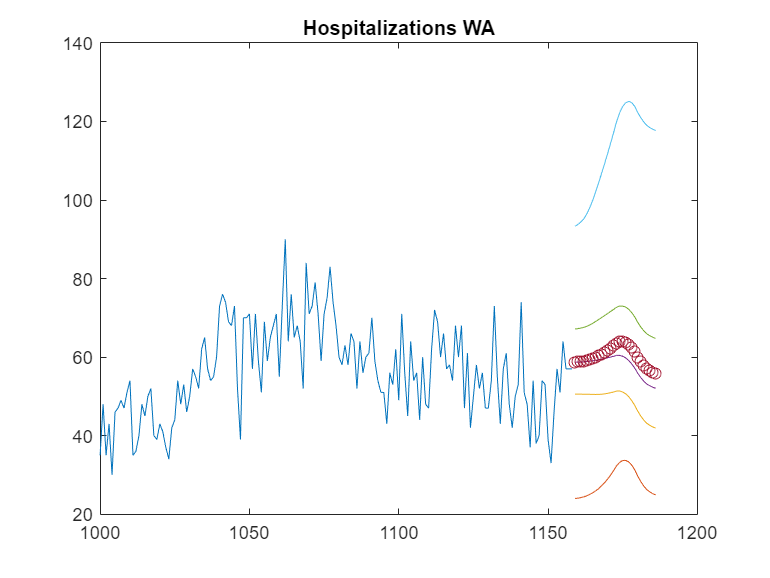

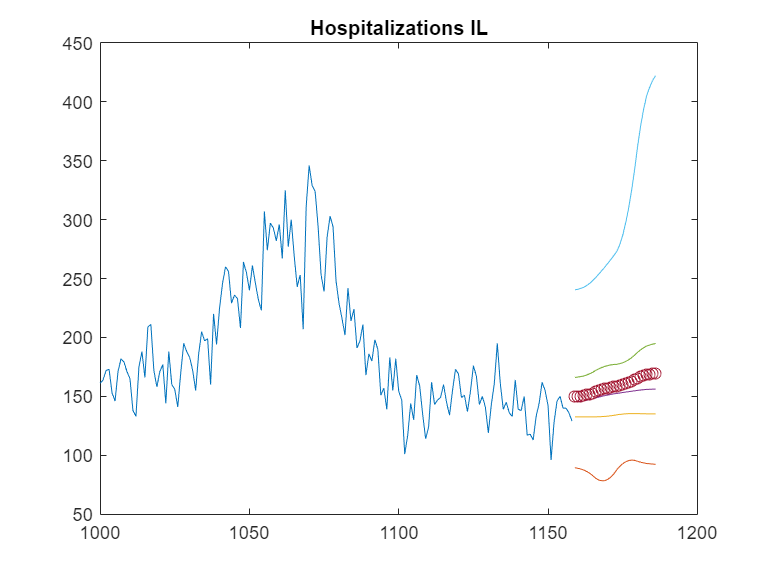

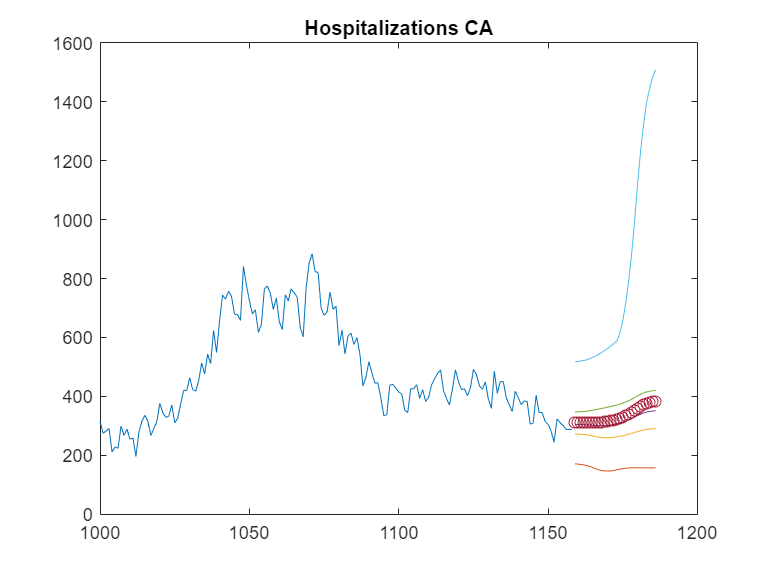

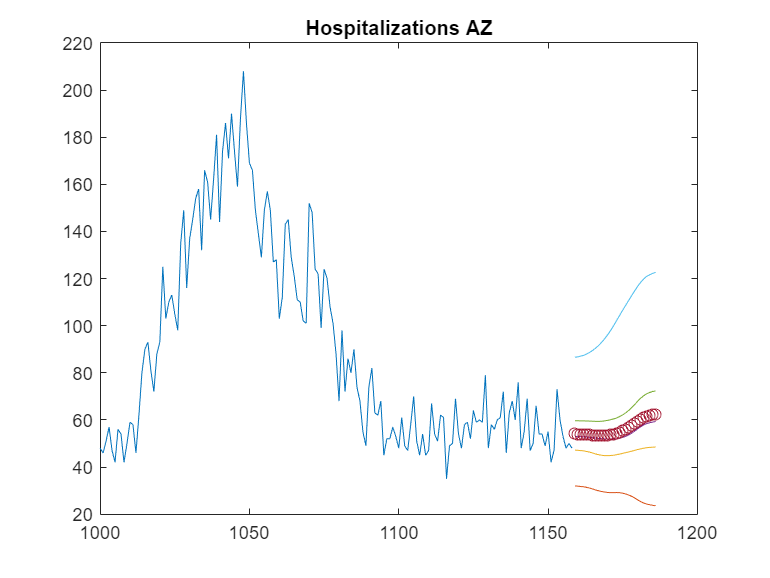

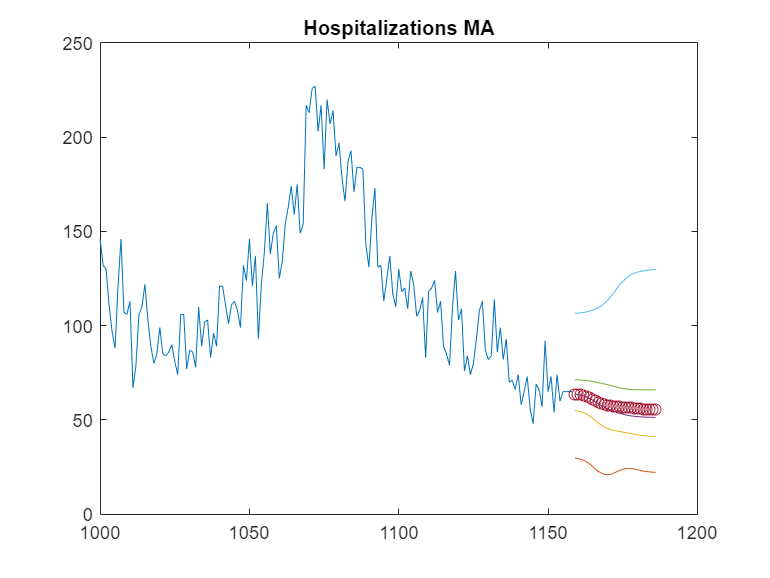

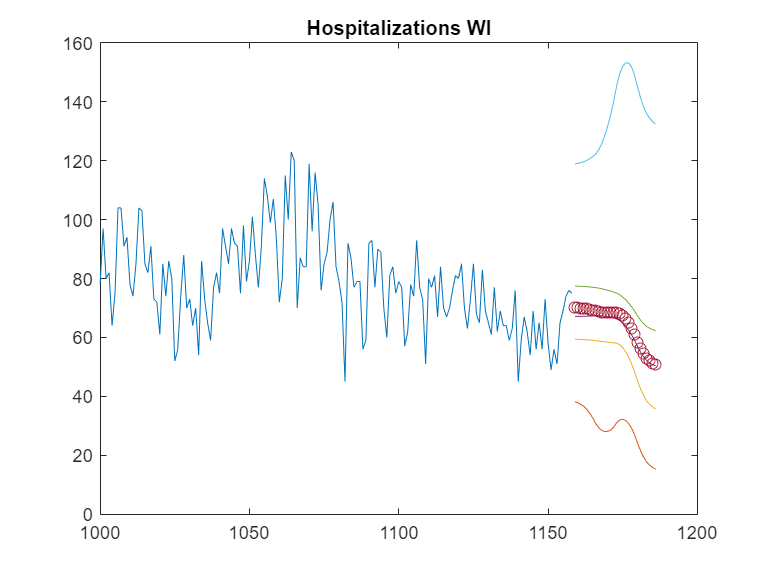

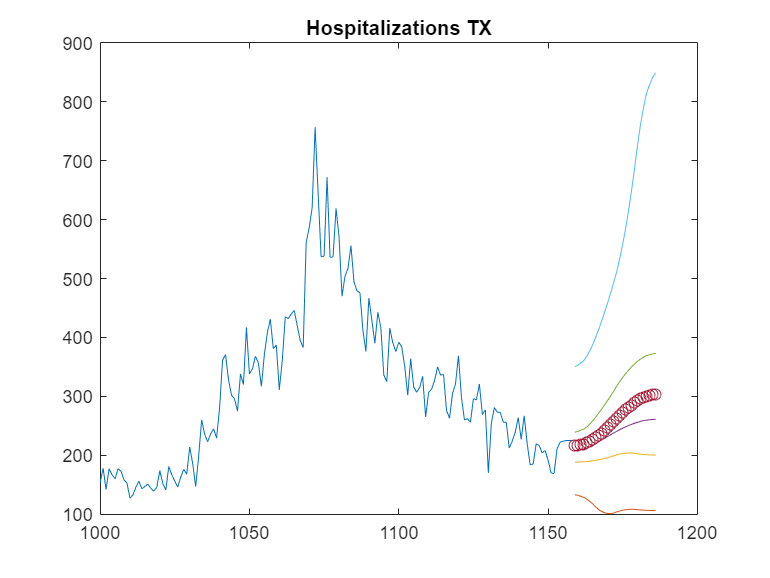

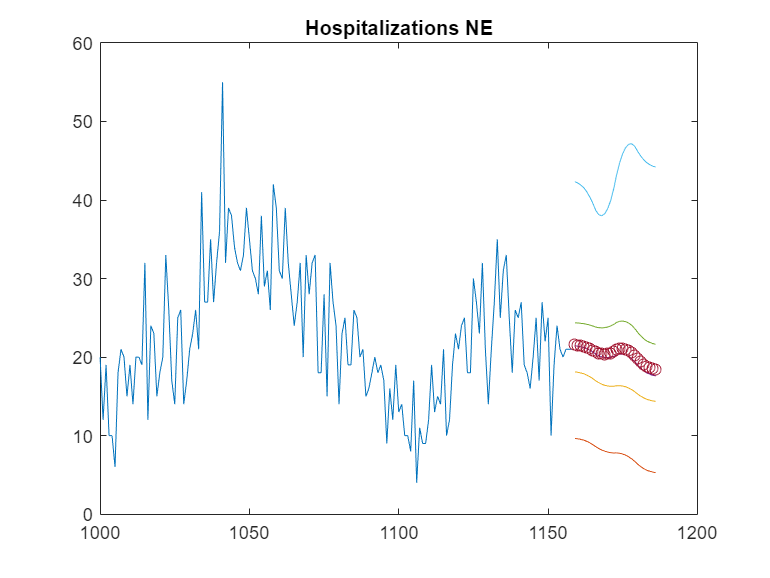


%% Load population data
popu = load('us_states_population_data.txt');
abvs = readcell('us_states_abbr_list.txt');
ns = length(abvs);

%% Convert hospital data to ReCOVER format
%172 last forecast
days_back =0; %4+(7*6);
fips_tab = readtable('reich_fips.txt', 'Format', '%s%s%s%d');
% zero_date = datetime(2021, 9, 1);
all_days = days(datetime(hosp_tab.date, 'InputFormat', 'yyyy/MM/dd') - zero_date);
bad_idx = all_days <= 0;
hosp_tab(bad_idx, :) = [];
all_days = all_days(~bad_idx);

maxt = max(all_days) - days_back;
fips = cell(ns, 1);
hosp_dat = nan(ns, maxt);

for cid = 1:length(abvs)
    fips(cid) = fips_tab.location(strcmp(fips_tab.abbreviation, abvs(cid)));
end
%%
for idx = 1:size(hosp_tab, 1)
    
    cid = find(strcmp(abvs, hosp_tab.state(idx)));
    if isempty(cid)
        disp(['Error at ' num2str(idx)]);
    end

    date_idx = all_days(idx);
    if date_idx <= maxt
        hosp_dat(cid, date_idx) = hosp_tab.previous_day_admission_adult_covid_confirmed(idx) + hosp_tab.previous_day_admission_pediatric_covid_confirmed(idx);%hosp_tab.previous_day_admission_influenza_confirmed(idx);
    end
end
%%
%Prepare matrix to collect coverage information if needed
%-------------------------
hosp_cov = nan(ns, maxt);
for idx = 1:size(hosp_tab, 1)
   
    cid = find(strcmp(abvs, hosp_tab.state(idx)));
    if isempty(cid)
        disp(['Error at ' num2str(idx)]);
    end

    date_idx = all_days(idx);
    if date_idx <= maxt
        hosp_dat(cid, date_idx) = hosp_tab.previous_day_admission_adult_covid_confirmed(idx) + hosp_tab.previous_day_admission_pediatric_covid_confirmed(idx);%hosp_tab.previous_day_admission_influenza_confirmed(idx);
        %hosp_cov(cid, date_idx) = hosp_tab.previous_day_admission_influenza_confirmed_coverage(idx);
    end
end

% hosp_dat = hosp_dat(:,1:7:floor(end/7)*7) + hosp_dat(:,2:7:floor(end/7)*7) + hosp_dat(:,3:7:floor(end/7)*7) + hosp_dat(:,4:7:floor(end/7)*7) + hosp_dat(:,5:7:floor(end/7)*7) + hosp_dat(:,6:7:floor(end/7)*7) + hosp_dat(:,7:7:floor(end/7)*7);

for cidx = 1:57
    figure;
    if cidx~=57
        thisquant = squeeze(nansum(quant_preds_deaths(cidx, :, [1 7 12 17 23]), 1));
        thismean = (nansum(mean_preds_deaths(cidx, :), 1));
    
        plot([1000:size(hosp_dat,2)], hosp_dat(cidx,1000:end)); hold on;
        plot([size(hosp_dat,2)+1:size(hosp_dat,2)+28], [thisquant]); hold on;
        plot([size(hosp_dat,2)+1:size(hosp_dat,2)+28],[thismean], 'o'); hold off;
        title(['Hospitalizations ' abvs{cidx}]);
    else
        thisquant = squeeze(nansum(quant_preds_deaths(1:56, :, [1 7 12 17 23]), 1));
        thismean = (nansum(mean_preds_deaths(1:56, :), 1));
    
        plot([1000:size(hosp_dat,2)], nansum(hosp_dat(:,1000:end),1)); hold on;
        plot([size(hosp_dat,2)+1:size(hosp_dat,2)+28], [thisquant]); hold on;
        plot([size(hosp_dat,2)+1:size(hosp_dat,2)+28],[thismean], 'o'); hold off;
        title(['Hospitalizations US']);
    end

    
end